Pick orbital parameters

clc;clear all;format short g;
MU = 3.986004418*10^5; % km^3/s^2
REarth = 6378.137; % km
alt = 590;e = 0;a = alt + REarth; % km
n = sqrt(MU/a^3); % rad/sec
P = 2*pi/n; % Seconds
i = acos(-(P/13662)^(7/3))*180/pi; % Degrees

ans =      0


Setup Scenario

startTime = datetime(2026,6,15,17,0,0);
stopTime = startTime + days(1); % Increase days to 31 to check GS access over the course of a month. Recommend disabling playback.
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

Set up COEs for scenario

semiMajorAxis = a*1000;
eccentricity = e;
inclination = i;
rightAscensionOfAscendingNode = 197.45;
argumentOfPeriapsis = 0;
trueAnomaly = 160;

sat = satellite(sc,semiMajorAxis,eccentricity,inclination, ...
    rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly);

**Access:**

USC

Create Ground Station

lat = 33.8960;
lon = -118.4004;
gs = groundStation(sc,lat,lon,'MinElevationAngle',10);

Pull Access Information from scenario

ac = access(gs,sat);
intvls = accessIntervals(ac);

Pull Position of satellite from scenario

[pos,~,timeOut] = states(sat);
SV_Sim.Position = pos;
SV_Sim.Time = timeOut;

Target

Create Ground Station

lat = -18.9185;
lon = 47.5211;
gs_target = groundStation(sc,lat,lon,'MinElevationAngle',10);

Pull Access Information from scenario

ac_target = access(gs_target,sat);
intvls_target = accessIntervals(ac_target);

**Power**

Pull Position of satellite from scenario

[pos,vel,timeOut] = states(sat);
SV_Sim.Position = pos;
SV_Sim.Time = timeOut;

Determine which positions are in sun and ecclipse

J_Time = juliandate(SV_Sim.Time); % Convert time to julian day format
for k = 1:size(SV_Sim.Time,2)
    r_temp = SV_Sim.Position(:,k)/(REarth*1000); % Convert position vector to earth radians
    SV_Sim.Sunlight(k) = sunlight(r_temp, J_Time(k), 'e');
end

Calculate power gathered by arrays

% Power from data sheet for EOL
P_Cell = 1.05; % Watts/cell
% Calculate total power generated by the solar arrays over the access intervals
SV_Sim.Pw_Arrays = SV_Sim.Sunlight.*P_Cell*24*0.3; % Watts

Calculate power used by baseline subsystems

SV_Sim.Pw_Lower_PPM = 0.693 * ones(1,size(SV_Sim.Time,2)); % Watts
SV_Sim.Pw_EPS = 0.4 * ones(1,size(SV_Sim.Time,2)); % Watts
SV_Sim.Pw_Beacon = 0.1*1.003 * ones(1,size(SV_Sim.Time,2))*0; % Watts
SV_Sim.Pw_MNav = 0.0055 * ones(1,size(SV_Sim.Time,2)); % Watts
SV_Sim.Pw_MTQ = 0.231 * ones(1,size(SV_Sim.Time,2)); % Watts
SV_Sim.Pw_Upper_PPM = 0.231 * ones(1,size(SV_Sim.Time,2)); % Watts
SV_Sim.Pw_Magnetometers = 0.33 * 2 * ones(1,size(SV_Sim.Time,2)); % Watts

Calculate power draw of infrequent use items.

AX-100

SV_Sim.Pw_AX100 = zeros(1,size(SV_Sim.Time,2)); % Create empty placeholder
% Run power_sim_dist for each pass
for k = 1:size(intvls.Duration,1)
    SV_Sim.Pw_AX100 = power_sim_dist(SV_Sim.Time, intvls.StartTime(k), intvls.Duration(k)/sampleTime, SV_Sim.Pw_AX100, 2.68);
end

Astroboard

SV_Sim.Pw_Astroboard = zeros(1,size(SV_Sim.Time,2)); % Create empty placeholder
% Run power_sim_dist for each pass
for k = 1:size(intvls_target,1)
    SV_Sim.Pw_Astroboard = power_sim_dist(SV_Sim.Time, intvls_target.StartTime(k), intvls_target.Duration(k)/sampleTime, SV_Sim.Pw_Astroboard, 0);
end
for k = 1:size(intvls,1)
    SV_Sim.Pw_Astroboard = power_sim_dist(SV_Sim.Time, intvls.StartTime(k), intvls.Duration(k)/sampleTime, SV_Sim.Pw_Astroboard, 0); %1.9623
end

Holonav

SV_Sim.Pw_Holonav = zeros(1,size(SV_Sim.Time,2)); % Create empty placeholder
% Run power_sim_dist for each pass
for k = 1:size(intvls_target,1)
    SV_Sim.Pw_Holonav = power_sim_dist(SV_Sim.Time, intvls_target.StartTime(k), intvls_target.Duration(k)/sampleTime, SV_Sim.Pw_Holonav, 0);
end
for k = 1:size(intvls,1)
    SV_Sim.Pw_Holonav = power_sim_dist(SV_Sim.Time, intvls.StartTime(k), intvls.Duration(k)/sampleTime, SV_Sim.Pw_Holonav, 0); %2.2656
end

SV Power Balance

% Sum power generated and expended at every point during the scenario.
SV_Sim.Pwr_Balance = SV_Sim.Pw_Arrays - (SV_Sim.Pw_Lower_PPM + SV_Sim.Pw_EPS + SV_Sim.Pw_Beacon + SV_Sim.Pw_MNav +...
    SV_Sim.Pw_MTQ + SV_Sim.Pw_Upper_PPM + SV_Sim.Pw_Magnetometers + SV_Sim.Pw_AX100 + SV_Sim.Pw_Astroboard + SV_Sim.Pw_Holonav);

SV Battery Capacity

% Set max and initial capacity of the batteries
Max_Capacity = 9.56*4; % W-Hrs
Initial_Capacity = 0.5*Max_Capacity;
% Perform first capacity calculation using initial capacity and first power
% balance.
SV_Sim.Battery_Capacity(1) = Initial_Capacity + SV_Sim.Pwr_Balance(1)/sampleTime; % W-Hrs 
% Ensure battery capacity does not exceed maximum capacity
if SV_Sim.Battery_Capacity(1) > Max_Capacity
    SV_Sim.Battery_Capacity(1) = Max_Capacity;
end
% Calculate the capacity of battery over full scenario.
for k = 1:(size(SV_Sim.Time,2)-1)
    SV_Sim.Battery_Capacity(k+1) = SV_Sim.Battery_Capacity(k) + 0.9*SV_Sim.Pwr_Balance(k)/sampleTime; % W-Hrs assuming 90% charge efficiency
    % Ensure battery capacity does not exceed maximum capacity at any step.
    if SV_Sim.Battery_Capacity(k+1) > Max_Capacity
        SV_Sim.Battery_Capacity(k+1) = Max_Capacity;
    end
end

Plot

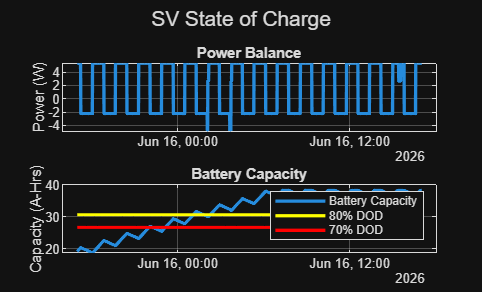

figure;
subplot(2,1,1);
plot(SV_Sim.Time, SV_Sim.Pwr_Balance, 'LineWidth', 2); hold on;
ylabel('Power (W)');
title('Power Balance'); grid on; hold off;
subplot(2,1,2);
plot(SV_Sim.Time, SV_Sim.Battery_Capacity, 'LineWidth', 2); hold on;
plot(SV_Sim.Time, Max_Capacity*0.8*ones(1,size(SV_Sim.Time,2)), 'y-', 'LineWidth', 2);
plot(SV_Sim.Time, Max_Capacity*0.7*ones(1,size(SV_Sim.Time,2)), 'r-', 'LineWidth', 2);
ylabel('Capacity (W-Hrs)');
legend('Battery Capacity', '80% DOD', '70% DOD')
title('Battery Capacity'); grid on; hold off;
sgtitle('SV State of Charge')

Average Pass Time

Total_Pass_Time = sum(intvls_target(:,"Duration"));
Number_Passes = size(intvls_target(:,"Duration"));
Average_Pass_Time = Total_Pass_Time.Duration/Number_Passes(1)

Average_Pass_Time =    450


Visualize

Note to self: Use function uipanel() to create a figure of the SV State of Charge and orbital visualization.

viewer = satelliteScenarioViewer(sc, ...
    "CameraReferenceFrame","Inertial", ...
    "PlaybackSpeedMultiplier",80, ...
    Position = [1 1 1920 1080], ...
    Dimension='3D',Name='MAVERIC Scenario');

% gifFileName = 'satellite_scenario_animation.gif';
% delayTime = 0.1; % Delay between frames in seconds
% 
% % Initialize the GIF file with the first frame
% exportgraphics(viewer, gifFileName); 
% 
% for t = sc.StartTime:sc.SampleTime:sc.StopTime
%     viewer.CurrentTime = t;
%     % Append subsequent frames to the GIF
%     exportgraphics(viewer.Parent, gifFileName, 'Append', true, 'DelayTime', delayTime);
% end